# RCS of Satellite

Create satellite surface from an STL file.

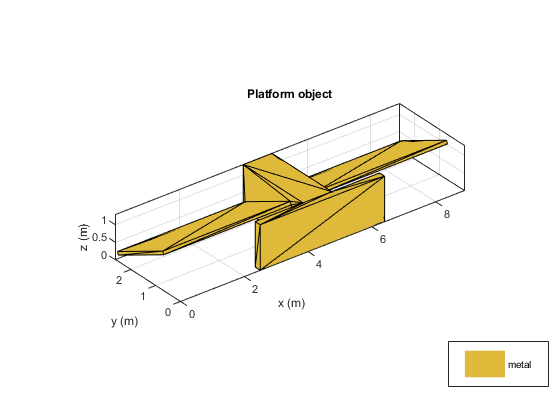

p = platform;
p.FileName = ['STK/sentinel1a.stl']; 
p.Units = 'm';
freq = 450e6;
figure
show(p)

Mesh the platform with edge length of 0.5

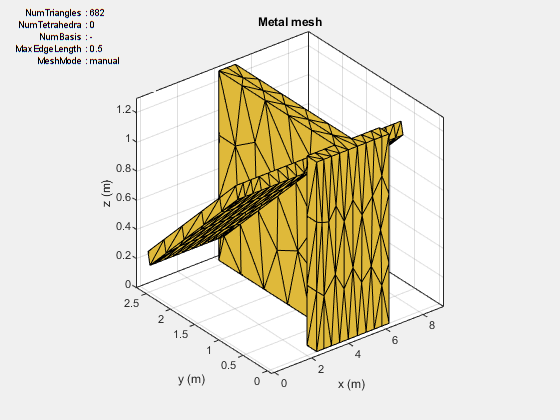

figure
mesh(p,'MaxEdgeLength', 0.5)

Sweep over the elevation with a vertically polarized E-field. Plot the RCS at 450 MHz in the azimuth plane.

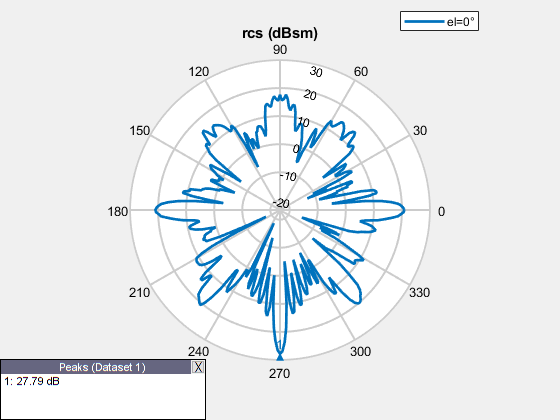

rcsval =    20.8417
   20.4517
   19.8075
   18.6993
   16.4068
   12.9757
    7.1707
   -4.8921
    1.6973
    8.5647


az =      0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49


el = 0

az = 0:1:360;
el = 0;
figure 
rcs(p,freq,az,el)
[rcsval,az,el] = rcs(p,freq,az,el)

pow = db2pow(rcsval);

'db2pow' requires Signal Processing Toolbox.

pow_avg = mean(pow);
RCSavg = mean(rcsval)
RCSavgp = pow2db(pow_avg)


*Copyright 2019 The MathWorks, Inc.*